# 4 Hands-on 3

"Please provide a solution and the corresponding explanation for 1.3."

Hands-on 3 excercise 1.3 dealt with the Fourier transform of a recorded signal. The sound of a piano playing a single note is loaded into Matlab. 

clear all; close all;

[h, Fs_h] = audioread("sounds/piano.wav"); % h is signal, Fs_h is sampling frequency
h=h(:,1);
sound(h,Fs_h);

We then plot the time signal from 0 to 1 seconds. 

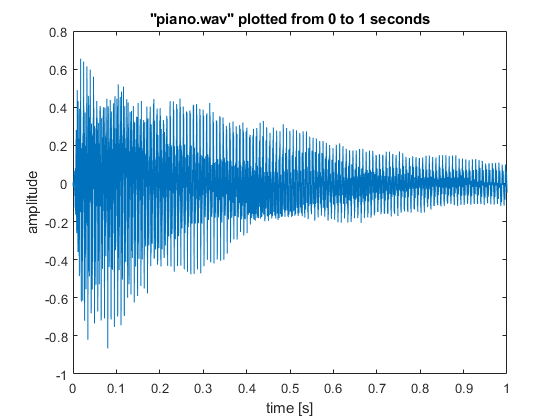

dt = 1/Fs_h; % sampling period
T = length(h)/Fs_h; % signal length
t = 0:dt:T-dt; % time vector

plot(t, h);
title('"piano.wav" plotted from 0 to 1 seconds')
xlim([0 1]); % plot the time signal from 0 to 1 seconds
xlabel('time [s]');
ylabel('amplitude');

figure

Thereafter, the spectrum of the whole signal plotted with Hz and dB on the x- and y-axis respectively.

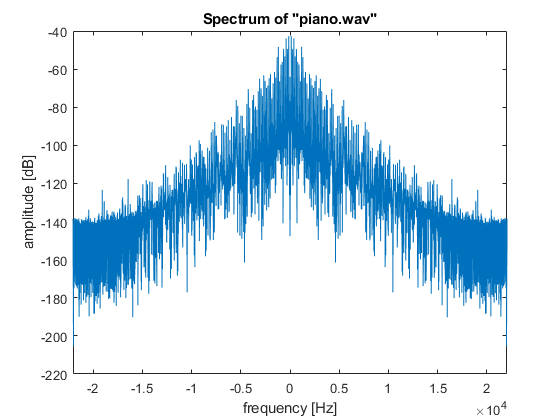

Y = fft(h); % computes Fourier transform of h, fft gives positive values before negative
Y = Y/(length(Y)); % scaling
df = 1/T;
f = (-Fs_h/2):df:(Fs_h/2 - df); % frequency vector
YdB = mag2db(abs(Y)); % same as writing 20*log10(abs(Y))

YdB = fftshift(YdB); % swaps left and right half (positive & negative)

plot(f,YdB);
title('Spectrum of "piano.wav"')
ax = gca;
ax.XLim = [-Fs_h/2 Fs_h/2]; % sets limits on x-axis
xlabel('frequency [Hz]');
ylabel('amplitude [dB]');

figure

To plot only the positive frequencies, including the DC component, we have to create new frequency and signal vectors, only containing values for the positive frequencies. MATLAB's fft-function returns the positive frequencies first, so the new vectors are created like this:

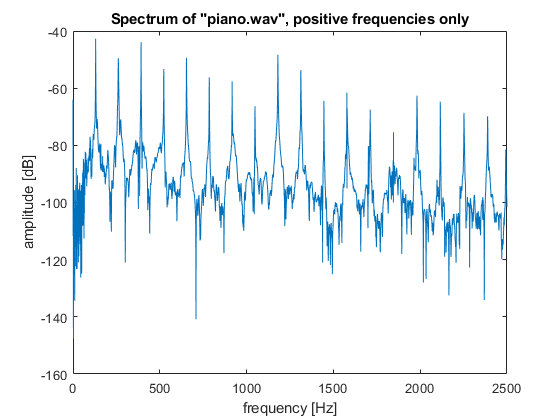

fpos = 0:df:(Fs_h/2 - df); % positive frequency vector
Ypos = Y(1:length(fpos)); % positive frequencies
YposdB = mag2db(abs(Ypos));

plot(fpos,YposdB);
title('Spectrum of "piano.wav", positive frequencies only')
ax = gca;
ax.XLim = [0 2500];
xlabel('frequency [Hz]');
ylabel('amplitude [dB]');

figure

From the power spectrum, we can estimate the fundamental frequency of the signal by looking at the spectral peaks. The fundamental frequency is defined as the lowest frequency of a periodic waveform (wikipedia). We see that the lowest peak is found at 130.43 Hz and therefore, with a precision of 0.5 Hz, we estimate the fundamental frequency of the signal to be f_0 = 130.5 Hz. 

The fundamental frequency is what we percieve as the musical pitch of a tone. 130.5 Hz roughly correlates with the fundamental of C3 on a piano, which sounds very similar to the tone played in 'piano.wav'. The other peaks in the spectrum represent the harmonics of the signal.

Now we want to synthesize the signal.

- *Synthesize the signal with a lenght of 2s in the frequency domain by approximating it via a harmonic series*

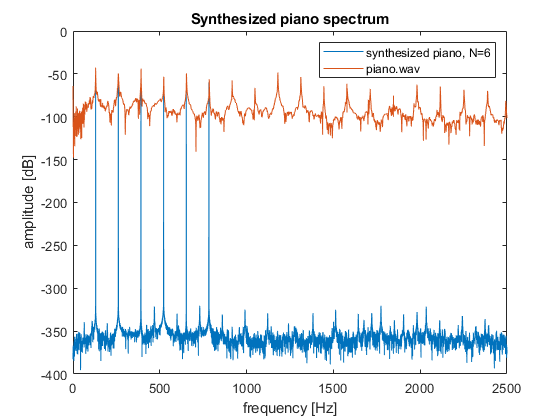

f0 = 130.5; % fundamental frequency in Hz
len = 2; % length in s of synth signal
N = 6; % number of components
Y_synth = zeros(1,len*Fs_h); % initialize synth signal
df = 1/len;
f = (-Fs_h/2):df:(Fs_h/2 - df); % frequency vector
t_synth = 0:dt:len-dt;% time vector

% 'a' is the amplitude we get from fourier analysis
a = ifft(YdB);
a = ifftshift(a);

for k=1:N % generate spectrum by adding components
  Y_synth = Y_synth + a(k)*sin(2*pi*k*f0*t_synth);
  % the sines have unit amplitude, but we multiply them with the amplitude
end

% to plot the synth signal spectrum, we go to the frequency domain
Y_synth_spec = fft(Y_synth);
Y_synth_spec = Y_synth_spec/(length(Y_synth_spec)); % scaling
Y_synth_spec = mag2db(abs(Y_synth_spec));
Y_synth_spec = fftshift(Y_synth_spec);

plot(f,Y_synth_spec); % synth signal spectrum
title('Synthesized piano spectrum')
ax = gca;
ax.XLim = [0 2500]; % sets limits on x-axis - maybe go higher? - like 44100/2 Hz?
xlabel('frequency [Hz]');
ylabel('amplitude [dB]');
hold on;
plot(fpos,YposdB);
legend('synthesized piano, N=6', 'piano.wav')

figure
% our normalized synth signal:
Y_synth = .5*Y_synth/max(Y_synth);
%sound(Y_synth,Fs_h); % plays sound signal

% without detail in the higher components it doesnt sound realisitic

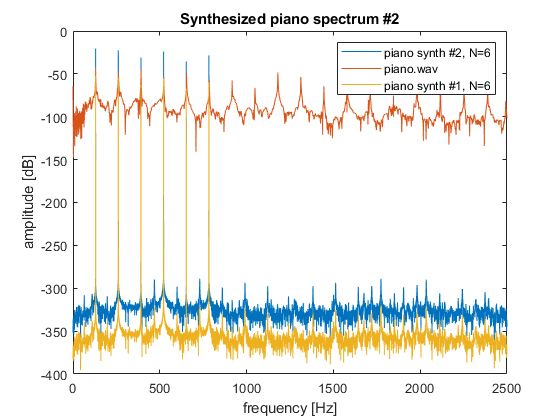

% synthesis, second part
% now we do the same as above, but including the phase
% by assigning complex numbers to the frequency bins

N = 6;

Y = fft(h); % computes Fourier transform of h
Y = ifft(Y);
Y = Y/(length(Y)); % scaling

phi = angle(Y);
r = mag2db(abs(Y));

Y_synthc = zeros(1,len*Fs_h); % initialize synth signal
df = 1/len;
f = (-Fs_h/2):df:(Fs_h/2 - df); % frequency vector
t_synth = 0:dt:len-dt;% time vector

for k=1:N % generate spectrum by adding components
  %Y_synthc = Y_synthc + r(k)*(exp(j*phi(k)) + exp(-j*phi(k)));
  %Y_synthc = Y_synthc + r(k)*2*(cos(phi(k)) + i*sin(phi(k)));
  Y_synthc = Y_synthc + a(k)*sin(2*pi*k*f0*t_synth + phi(k));
end

% ...
Y_synthc_spec = fft(Y_synth);
Y_synthc_spec = Y_synthc_spec/(length(Y_synthc_spec)); % scaling
Y_synthc_spec = mag2db(abs(Y_synthc_spec));
Y_synthc_spec = fftshift(Y_synthc_spec);

plot(f,Y_synthc_spec); % synth signal spectrum
title('Synthesized piano spectrum #2')
ax = gca;
ax.XLim = [0 2500]; % sets limits on x-axis - maybe go higher? - like 44100/2 Hz?
xlabel('frequency [Hz]');
ylabel('amplitude [dB]');
hold on;
plot(fpos,YposdB);
plot(f,Y_synth_spec);
legend('piano synth #2, N=6', 'piano.wav', 'piano synth #1, N=6')

figure
% our normalized synth signal:
Y_synthc = .5*Y_synthc/max(Y_synthc);
sound(Y_synthc,Fs_h); % plays sound signal